# WBR腿部五连杆机构分析

## 1 参数定义

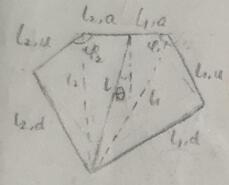

leg = struct;
leg.l = sym("l");
leg.theta = sym("theta");
leg.phi_1 = sym("varphi_1");
leg.phi_2 = sym("varphi_2");
leg.l_1a = sym("l_1_a");
leg.l_1u = sym("l_1_u");
leg.l_1d = sym("l_1_d");
leg.l_2a = sym("l_2_a");
leg.l_2u = sym("l_2_u");
leg.l_2d = sym("l_2_d");

## 2 逆运动学

逆运动学问题：$(\varphi_1,\varphi_2)=f(l,\theta)$

$l_1=\sqrt{l_{1,a}^2+l^2+2l_{1,a}lsin\theta}$    (2.1)

$l_2=\sqrt{l_{2,a}^2+l^2-2l_{2,a}lsin\theta}$    (2.2)

$\varphi_1=acos\frac{l_1^2+l_{1,a}^2-l^2}{2l_1l_{1,a}}+acos\frac{l_1^2+l_{1,u}^2-l_{1,d}^2}{2l_1l_{1,u}}$    (2.3)

$\varphi_2=acos\frac{l_2^2+l_{2,a}^2-l^2}{2l_2l_{2,a}}+acos\frac{l_2^2+l_{2,u}^2-l_{2,d}^2}{2l_2l_{2,u}}$    (2.4)

leg.l_1 = sqrt(leg.l_1a^2+leg.l^2+2*leg.l_1a*leg.l*sin(leg.theta));
leg.l_2 = sqrt(leg.l_2a^2+leg.l^2-2*leg.l_2a*leg.l*sin(leg.theta));
leg.ikine.phi_1 = acos((leg.l_1^2+leg.l_1a^2-leg.l^2)/(2*leg.l_1*leg.l_1a)) ...
                 +acos((leg.l_1^2+leg.l_1u^2-leg.l_1d^2)/(2*leg.l_1*leg.l_1u));
leg.ikine.phi_2 = acos((leg.l_2^2+leg.l_2a^2-leg.l^2)/(2*leg.l_2*leg.l_2a)) ...
                 +acos((leg.l_2^2+leg.l_2u^2-leg.l_2d^2)/(2*leg.l_2*leg.l_2u));

## 3 正运动学

正运动学问题：$(l,\theta_l)=f^{-1}(\varphi_1,\varphi_2)$

$(l_{1,a}-l_{1,u}cos\varphi_1+lsin\theta)^2+(l_{1,u}sin\varphi_1-lcos\theta)^2=l_{1,d}^2$    (3.1)

$(l_{2,a}-l_{2,u}cos\varphi_2-lsin\theta)^2+(l_{2,u}sin\varphi_2-lcos\theta)^2=l_{2,d}^2$    (3.2)

令 $x_e = lsin\theta$ , $y_e=lcos\theta$，记 $x_i=l_{i,a}-l_{i,u}cos\varphi_i$ ,  $y_i = l_{i,u}sin\varphi_i$ , $i=1,2$

方程组 (3.1)(3.2) 改写为

$(x_e+x_1)^2+(y_e-y_1)^2=l_{1,d}^2$    (3.3)

$(x_e-x_2)^2+(y_e-y_2)^2=l_{2,d}^2$    (3.4)

leg.x_e = sym("x_e");
leg.y_e = sym("y_e");
leg.x_1 = sym("x_1");
leg.y_1 = sym("y_1");
leg.x_2 = sym("x_2");
leg.y_2 = sym("y_2");

leg.fkine.xi = [leg.l_1a-leg.l_1u*cos(leg.phi_1)
                leg.l_2a-leg.l_2u*cos(leg.phi_2)];
leg.fkine.yi = [leg.l_1u*sin(leg.phi_1)
                leg.l_2u*sin(leg.phi_2)];

leg.fkine_eq = sym("eq",[2,1]);
leg.fkine_eq(1) = (leg.x_e+leg.x_1)^2+(leg.y_e-leg.y_1)^2-leg.l_1d^2;
leg.fkine_eq(2) = (leg.x_e-leg.x_2)^2+(leg.y_e-leg.y_2)^2-leg.l_2d^2;
leg.fkine_sol = solve(leg.fkine_eq,[leg.x_e,leg.y_e]);
leg.fkine.x_e = simplify(leg.fkine_sol.x_e(1));
leg.fkine.y_e = simplify(leg.fkine_sol.y_e(1));
leg.fkine.xy2lphi = @(xe,ye)[sqrt(xe^2+ye^2);atan2(xe,ye)];

求解结果


$$x_e=
\frac{y_{1}\sigma_1-y_{2}\sigma_1+{l_{1,d}}^2\,x_{1}+{l_{1,d}}^2\,x_{2}-{l_{2,d}}^2\,x_{1}-{l_{2,d}}^2\,x_{2}+x_{1}\,{x_{2}}^2-{x_{1}}^2\,x_{2}-x_{1}\,{y_{1}}^2-x_{1}\,{y_{2}}^2+x_{2}\,{y_{1}}^2+x_{2}\,{y_{2}}^2-{x_{1}}^3+{x_{2}}^3+2\,x_{1}\,y_{1}\,y_{2}-2\,x_{2}\,y_{1}\,y_{2}}{2\,\left({x_{1}}^2+2\,x_{1}\,x_{2}+{x_{2}}^2+{y_{1}}^2-2\,y_{1}\,y_{2}+{y_{2}}^2\right)}$$



$$y_e=
\frac{x_{1}\sigma_1+x_{2}\sigma_1-{l_{1,d}}^2\,y_{1}+{l_{1,d}}^2\,y_{2}+{l_{2,d}}^2\,y_{1}-{l_{2,d}}^2\,y_{2}+{x_{1}}^2\,y_{1}+{x_{1}}^2\,y_{2}+{x_{2}}^2\,y_{1}+{x_{2}}^2\,y_{2}-y_{1}\,{y_{2}}^2-{y_{1}}^2\,y_{2}+{y_{1}}^3+{y_{2}}^3+2\,x_{1}\,x_{2}\,y_{1}+2\,x_{1}\,x_{2}\,y_{2}}{2\,\left({x_{1}}^2+2\,x_{1}\,x_{2}+{x_{2}}^2+{y_{1}}^2-2\,y_{1}\,y_{2}+{y_{2}}^2\right)}$$


其中


$$\sigma_1=
\sqrt{-{\left(-{l_{1,d} }^2 -2\,l_{1,d} \,l_{2,d} -{l_{2,d} }^2 +{x_1 }^2 +2\,x_1 \,x_2 +{x_2 }^2 +{y_1 }^2 -2\,y_1 \,y_2 +{y_2 }^2 \right)}\,{\left(-{l_{1,d} }^2 +2\,l_{1,d} \,l_{2,d} -{l_{2,d} }^2 +{x_1 }^2 +2\,x_1 \,x_2 +{x_2 }^2 +{y_1 }^2 -2\,y_1 \,y_2 +{y_2 }^2 \right)}}$$


## 4 雅可比矩阵

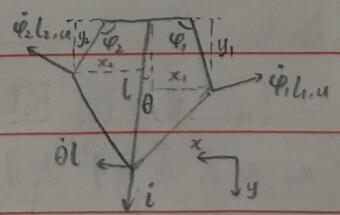

直接对式 (2.3)(2.4) 或方程组 (3.1)(3.2) 的解求偏导的结果非常复杂，而根据速度关系可以得到表达式相对简单的雅可比矩阵，即

$\dot{q}=J^{-1}\dot{p}$    (4.1)

其中，$q=\left[\matrix{
\varphi_1 & \varphi_2
}\right]^T$，$p=\left[\matrix{
l & \theta
}\right]^T$

令 $x_e = lsin\theta$ , $y_e=lcos\theta$，记 $x_i=l_{i,a}-l_{i,u}cos\varphi_i$ ,  $y_i = l_{i,u}sin\varphi_i$ , $i=1,2$

速度约束方程

$\left(\dot\varphi_1l_{1,u}\left[\matrix{-sin\varphi_1 \cr cos\varphi_1}\right]\right)^T\left[\matrix{x_e+x_1 \cr y_e-y_1}\right]
=
\left(\dot l\left[\matrix{sin\theta \cr cos\theta}\right]+\dot\theta l\left[\matrix{cos\theta \cr -sin\theta}\right]\right)^T\left[\matrix{x_e+x_1 \cr y_e-y_1}\right]$    (4.2)

$\left(\dot\varphi_2l_{2,u}\left[\matrix{sin\varphi_2 \cr cos\varphi_2}\right]\right)^T\left[\matrix{x_e-x_2 \cr y_e-y_2}\right]
=
\left(\dot l\left[\matrix{sin\theta \cr cos\theta}\right]+\dot\theta l\left[\matrix{cos\theta \cr -sin\theta}\right]\right)^T\left[\matrix{x_e-x_2 \cr y_e-y_2}\right]$    (4.3)

由式 (4.2)(4.3) 可得

$\frac{\partial\varphi_1}{\partial l}=
\frac{1}{l_{1,u}}\frac{(x_e+x_1)sin\theta+(y_e-y_1)cos\theta}{-(x_e+x_1)sin\varphi_1+(y_e-y_1)cos\varphi_1}$    (4.4)

$\frac{\partial\varphi_1}{\partial\theta}=
\frac{l}{l_{1,u}}\frac{(x_e+x_1)cos\theta-(y_e-y_1)sin\theta}{-(x_e+x_1)sin\varphi_1+(y_e-y_1)cos\varphi_1}$    (4.5)

$\frac{\partial\varphi_2}{\partial l}=
\frac{1}{l_{2,u}}\frac{(x_e-x_2)sin\theta+(y_e-y_2)cos\theta}{(x_e-x_2)sin\varphi_2+(y_e-y_2)cos\varphi_2}$    (4.6)

$\frac{\partial\varphi_2}{\partial\theta}=
\frac{l}{l_{2,u}}\frac{(x_e-x_2)cos\theta-(y_e-y_2)sin\theta}{(x_e-x_2)sin\varphi_2+(y_e-y_2)cos\varphi_2}$    (4.7)

$J=\left[\matrix{
\frac{\partial\varphi_1}{\partial l} & \frac{\partial\varphi_1}{\partial\theta} \cr \frac{\partial\varphi_2}{\partial l} & \frac{\partial\varphi_2}{\partial\theta}
}\right]^{-1}$    (4.8)

leg.Pphi1Pl = @(l,theta,phi,xe,ye,xi,yi,li_u)1/li_u(1) ...
                      *((xe+xi(1))*sin(theta)+(ye-yi(1))*cos(theta)) ...
                      /(-(xe+xi(1))*sin(phi(1))+(ye-yi(1))*cos(phi(1)));
leg.Pphi1Ptheta = @(l,theta,phi,xe,ye,xi,yi,li_u)l/li_u(1) ...
                      *((xe+xi(1))*cos(theta)-(ye-yi(1))*sin(theta)) ...
                      /(-(xe+xi(1))*sin(phi(1))+(ye-yi(1))*cos(phi(1)));
leg.Pphi2Pl = @(l,theta,phi,xe,ye,xi,yi,li_u)1/li_u(2) ...
                      *((xe-xi(2))*sin(theta)+(ye-yi(2))*cos(theta)) ...
                      /((xe-xi(2))*sin(phi(2))+(ye-yi(2))*cos(phi(2)));
leg.Pphi2Ptheta = @(l,theta,phi,xe,ye,xi,yi,li_u)l/li_u(2) ...
                      *((xe-xi(2))*cos(theta)-(ye-yi(2))*sin(theta)) ...
                      /((xe-xi(2))*sin(phi(2))+(ye-yi(2))*cos(phi(2)));
leg.jacob = @(l,theta,phi,xe,ye,xi,yi,li_u)inv([ ...
                leg.Pphi1Pl(l,theta,phi,xe,ye,xi,yi,li_u), ...
                leg.Pphi1Ptheta(l,theta,phi,xe,ye,xi,yi,li_u); ...
                leg.Pphi2Pl(l,theta,phi,xe,ye,xi,yi,li_u), ...
                leg.Pphi2Ptheta(l,theta,phi,xe,ye,xi,yi,li_u)]);

## 5 动态静力学

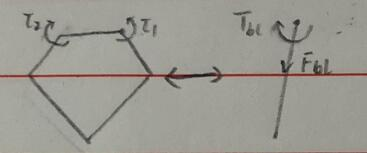

记 $\gamma=\left[\matrix{F_{bl} & T_{bl}}\right]^T$，$\tau=\left[\matrix{\tau_1 & \tau_2}\right]^T$

根据虚功原理可得

$\tau=J^T\gamma$    (5.1)

## 6 动力学参数

$\theta_l=\theta+\theta_b$    (6.1)

$m_l=\sum{m_{i,p}} \ (i=1,2\ p=u,d)$    (6.2)

通过插值拟合得到腿部质心位置和惯量关于 $l$ 的近似函数

$(l_w,l_b)=f_{l,c}(l)$    (6.3）

$I_l=f_{l,I}(l)$    (6.4)

## 附录1 运动学验证

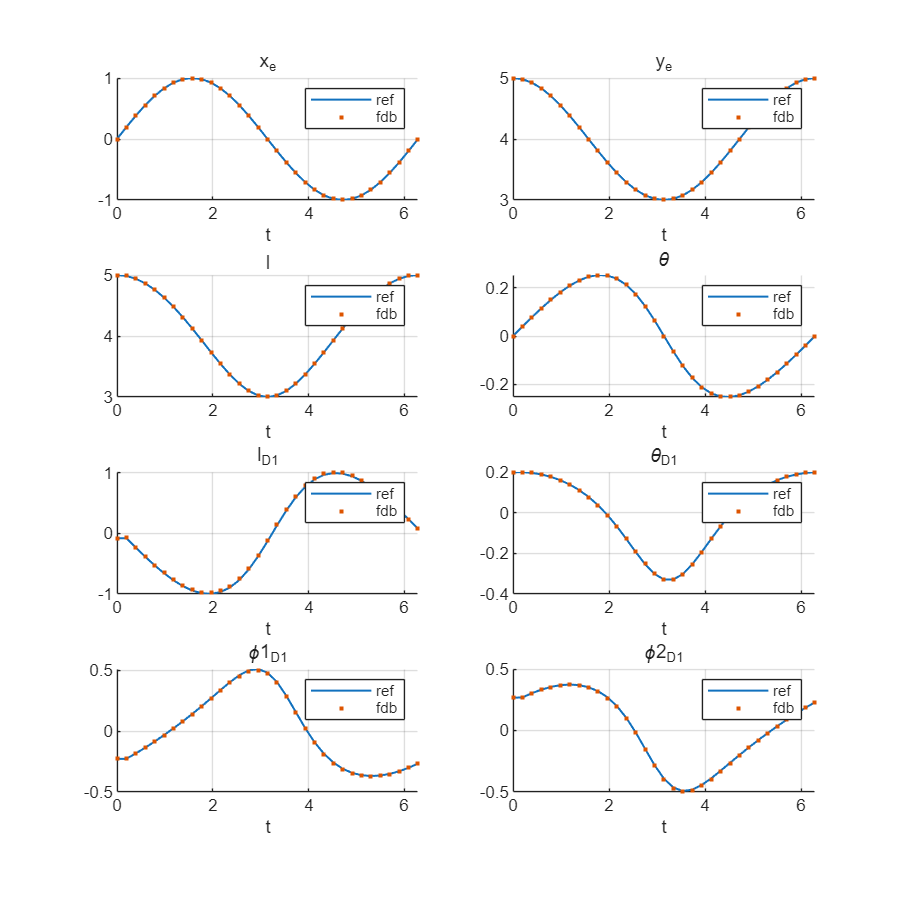

% leg parameters (test)
leg_test = struct( ...
  "l_1_a", 1, ...
  "l_1_u", 3, ...
  "l_1_d", 5, ...
  "l_2_a", 1, ...
  "l_2_u", 3, ...
  "l_2_d", 5);
% kinematic function
leg_test.ikine = matlabFunction(subs([leg.ikine.phi_1;leg.ikine.phi_2], ...
                    {sym("l_1_a"),sym("l_1_u"),sym("l_1_d"), ...
                     sym("l_2_a"),sym("l_2_u"),sym("l_2_d")}, ...
                    {leg_test.l_1_a,leg_test.l_1_u,leg_test.l_1_d, ...
                     leg_test.l_2_a,leg_test.l_2_u,leg_test.l_2_d}));
leg_test.xi = matlabFunction(subs(leg.fkine.xi, ...
                    {sym("l_1_a"),sym("l_1_u"),sym("l_1_d"), ...
                     sym("l_2_a"),sym("l_2_u"),sym("l_2_d")}, ...
                    {leg_test.l_1_a,leg_test.l_1_u,leg_test.l_1_d, ...
                     leg_test.l_2_a,leg_test.l_2_u,leg_test.l_2_d}));
leg_test.yi = matlabFunction(subs(leg.fkine.yi, ...
                    {sym("l_1_a"),sym("l_1_u"),sym("l_1_d"), ...
                     sym("l_2_a"),sym("l_2_u"),sym("l_2_d")}, ...
                    {leg_test.l_1_a,leg_test.l_1_u,leg_test.l_1_d, ...
                     leg_test.l_2_a,leg_test.l_2_u,leg_test.l_2_d}));
leg_test.xe = matlabFunction(subs(leg.fkine.x_e, ...
                  {sym("l_1_d"),sym("l_2_d")}, ...
                  {leg_test.l_1_d,leg_test.l_2_d}));
leg_test.ye = matlabFunction(subs(leg.fkine.y_e, ...
                  {sym("l_1_d"),sym("l_2_d")}, ...
                  {leg_test.l_1_d,leg_test.l_2_d}));
% reference trajectory
dt = 2*pi/32;
t = 0:dt:2*pi;
xe_ref_t = sin(t);
ye_ref_t = 4+cos(t);
l_ref_t = sqrt(xe_ref_t.^2+ye_ref_t.^2);
theta_ref_t = atan2(xe_ref_t,ye_ref_t);
% feedback trajectory
phi_t = zeros(2,size(t,2));
xi_t = zeros(2,size(t,2));
yi_t = zeros(2,size(t,2));
xe_t = zeros(1,size(t,2));
ye_t = zeros(1,size(t,2));
l_t = zeros(1,size(t,2));
theta_t = zeros(1,size(t,2));
for i = 1:size(t,2)
  phi_t(:,i) = leg_test.ikine(l_ref_t(i),theta_ref_t(i));
  xi_t(:,i) = leg_test.xi(phi_t(1,i),phi_t(2,i));
  yi_t(:,i) = leg_test.yi(phi_t(1,i),phi_t(2,i));
  xe_t(i) = leg_test.xe(xi_t(1,i),xi_t(2,i),yi_t(1,i),yi_t(2,i));
  ye_t(i) = leg_test.ye(xi_t(1,i),xi_t(2,i),yi_t(1,i),yi_t(2,i));
  l_t(i) = sqrt(xe_t(i)^2+ye_t(i)^2);
  theta_t(i) = atan2(xe_t(i),ye_t(i));
end
% speed
l_D1_ref_t = (l_ref_t(2:end)-l_ref_t(1:end-1))/dt;
l_D1_ref_t = [l_D1_ref_t(1),l_D1_ref_t];
theta_D1_ref_t = (theta_ref_t(2:end)-theta_ref_t(1:end-1))/dt;
theta_D1_ref_t = [theta_D1_ref_t(1),theta_D1_ref_t];
phi_D1_t = (phi_t(:,2:end)-phi_t(:,1:end-1))/dt;
phi_D1_t = [phi_D1_t(:,1),phi_D1_t];
phi_D1_ref_t = zeros(2,size(t,2));
l_D1_t = zeros(1,size(t,2));
theta_D1_t = zeros(1,size(t,2));
for i = 1:size(t,2)
  J = leg.jacob(l_t(i),theta_t(i),phi_t(:,i),xe_t(i),ye_t(i), ...
                xi_t(:,i),yi_t(:,i),[leg_test.l_1_u;leg_test.l_2_u]);
  phi_D1_ref_t(:,i) = J\[l_D1_ref_t(i);theta_D1_ref_t(i)];
  p = J*phi_D1_t(:,i);
  l_D1_t(i) = p(1);
  theta_D1_t(i) = p(2);
end
% plot
figure;
subplot(4,2,1); hold on; grid on;
plot(t,xe_ref_t,"lineWidth",1);
plot(t,xe_t,".","lineWidth",1);
legend("ref","fdb"); xlabel("t"); title("x_e");
subplot(4,2,2); hold on; grid on;
plot(t,ye_ref_t,"lineWidth",1);
plot(t,ye_t,".","lineWidth",1);
legend("ref","fdb"); xlabel("t"); title("y_e");
subplot(4,2,3); hold on; grid on;
plot(t,l_ref_t,"lineWidth",1);
plot(t,l_t,".","lineWidth",1);
legend("ref","fdb"); xlabel("t"); title("l");
subplot(4,2,4); hold on; grid on;
plot(t,theta_ref_t,"lineWidth",1);
plot(t,theta_t,".","lineWidth",1);
legend("ref","fdb"); xlabel("t"); title("\theta");
subplot(4,2,5); hold on; grid on;
plot(t,l_D1_ref_t(:),"lineWidth",1);
plot(t,l_D1_t(1,:),".","lineWidth",1);
legend("ref","fdb"); xlabel("t"); title("l_{D1}");
subplot(4,2,6); hold on; grid on;
plot(t,theta_D1_ref_t(:),"lineWidth",1);
plot(t,theta_D1_t(:),".","lineWidth",1);
legend("ref","fdb"); xlabel("t"); title("\theta_{D1}");
set(gcf,"position",[0,0,600,600]);
subplot(4,2,7); hold on; grid on;
plot(t,phi_D1_ref_t(1,:),"lineWidth",1);
plot(t,phi_D1_t(1,:),".","lineWidth",1);
legend("ref","fdb"); xlabel("t"); title("\phi1_{D1}");
subplot(4,2,8); hold on; grid on;
plot(t,phi_D1_ref_t(2,:),"lineWidth",1);
plot(t,phi_D1_t(2,:),".","lineWidth",1);
legend("ref","fdb"); xlabel("t"); title("\phi2_{D1}");